clear all
close all
clc

## Loading In Audio

handel = load("handel.mat")

handel = struct with fields:
     y: [73113×1 double]
    Fs: 8192


laughter = load("laughter.mat")

laughter = struct with fields:
     y: [52634×1 double]
    Fs: 8192


## Creating our 2kHz lowpass filter

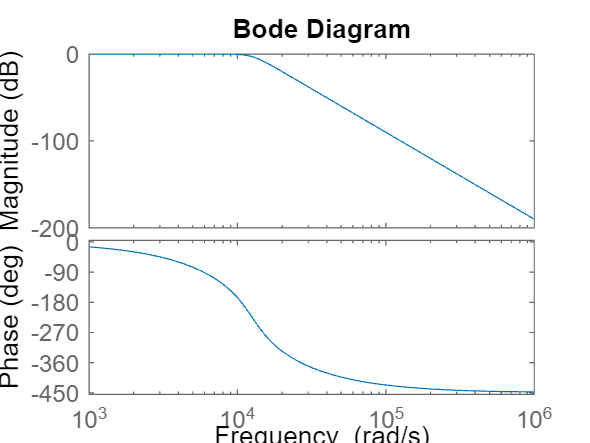

fc = 2000; % Hz Cutoff Frequency
[num, den] = butter(5,2*pi*fc,'s');
H_butter = tf(num,den);
clear num den
bodeplot(H_butter)

## Normalizing the signals to 0,2 and upsampling to 120 kHz

handel.y = (1.+(handel.y./(max(abs(handel.y)))));
laughter.y = (1.+(laughter.y./(max(abs(laughter.y)))));
handel.y = resample(handel.y,120000,73113);

handel = struct with fields:
     y: [120000×1 double]
    Fs: 8192


laughter.y = resample(laughter.y,120000,52634);

laughter = struct with fields:
     y: [120000×1 double]
    Fs: 8192
